p = design(patchMicrostripInsetfed,2.4e9)%this will design a freq. specific antenna, the antenna resonates with 2.4

p =   patchMicrostripInsetfed with properties:

               Length: 0.0562
                Width: 0.0562
               Height: 0.0031
            Substrate: [1×1 dielectric]
    PatchCenterOffset: [0 0]
           FeedOffset: [-0.0625 0]
       StripLineWidth: 0.0036
          NotchLength: 0.0083
           NotchWidth: 0.0062
    GroundPlaneLength: 0.1249
     GroundPlaneWidth: 0.1249
                 Tilt: 0
             TiltAxis: [1 0 0]
                 Load: [1×1 lumpedElement]




%
%   
%    die=dielectric('Taconic RF-35')
%    p.Substrate=die
%
%    The following code will overload the memory, and will eventually
%    crash, i'm certain it is not a hardware malfunction,
%
%           Solving for the impedance seems too much for the program, it
%           seems...

Z = impedance(p,2.4e9)

Z = 41.7414 - 10.8979i


die=dielectric('Taconic RF-35')

die =   dielectric with properties:

           Name: 'Taconic RF-35'
       EpsilonR: 3.5000
    LossTangent: 0.0018
      Thickness: 0.0060

For more materials see catalog

p.Substrate=die

p =   patchMicrostripInsetfed with properties:

               Length: 0.0562
                Width: 0.0562
               Height: 0.0031
            Substrate: [1×1 dielectric]
    PatchCenterOffset: [0 0]
           FeedOffset: [-0.0625 0]
       StripLineWidth: 0.0036
          NotchLength: 0.0083
           NotchWidth: 0.0062
    GroundPlaneLength: 0.1249
     GroundPlaneWidth: 0.1249
                 Tilt: 0
             TiltAxis: [1 0 0]
                 Load: [1×1 lumpedElement]


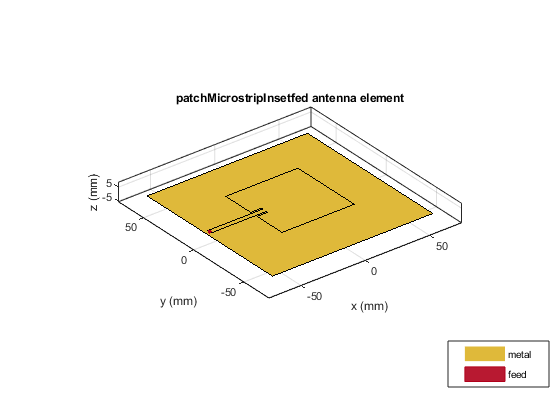

show(p)

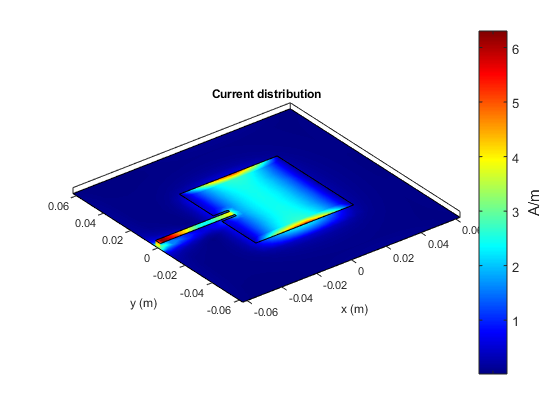

current(p,2.4e9)

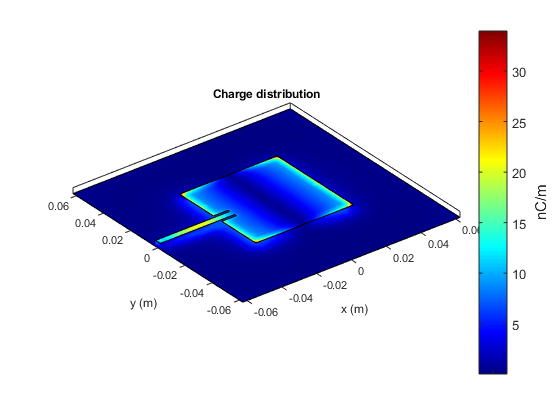

charge(p, 2.4e9)

pattern(p, 2.4e9)
freq = linspace(2.35e9,2.45e9,21)

freq = 	1.0e+09 *

    2.3500    2.3550    2.3600    2.3650    2.3700    2.3750    2.3800    2.3850    2.3900    2.3950    2.4000    2.4050    2.4100    2.4150    2.4200    2.4250    2.4300    2.4350    2.4400    2.4450    2.4500


s = sparameters(p,freq,50) 

s =   sparameters: S-parameters object

       NumPorts: 1
    Frequencies: [21×1 double]
     Parameters: [1×1×21 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


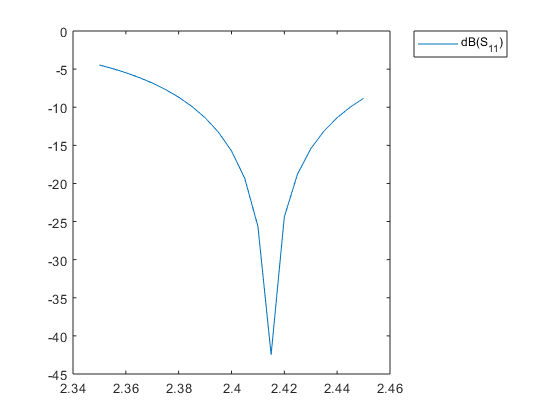

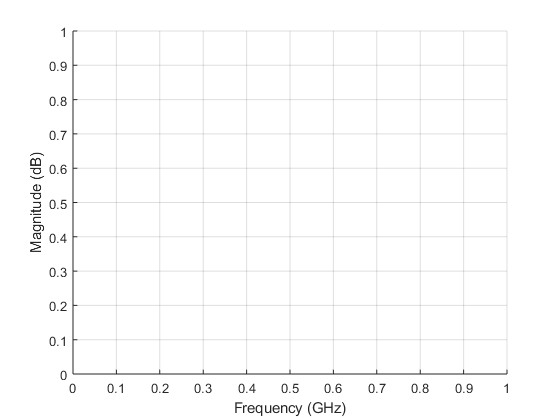

rfplot(s)